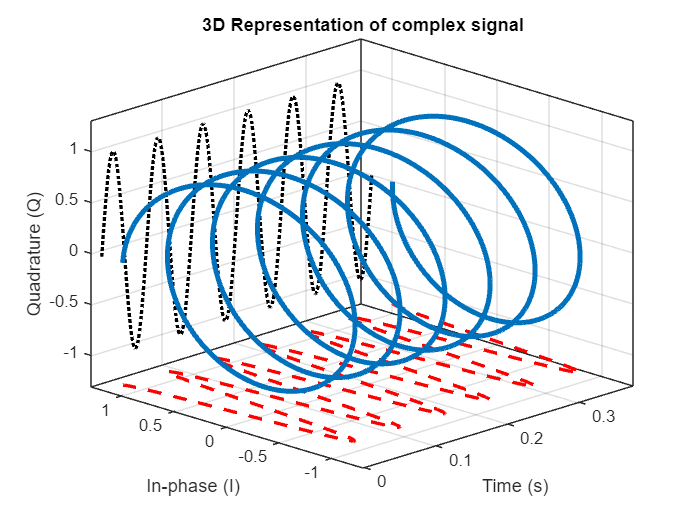

% Extract simulation data

t = out.I.Time;
I = out.I.Data;
Q = out.Q.Data;

w = 50; % Angular frequency used in simulink rad/s

% period
T = 2*pi/w;

% Display only first 3 cycles

idx = t <= 3*T;

t = t(idx);
I = I(idx);
Q = Q(idx);
figure('Color','w')

%helix

plot3(t,I,Q,'LineWidth',3)
hold on

% projection on Time-I plane

plot3(t,I,-1.2*ones(size(t)),'r--','LineWidth',2)

% projection on Time-Q plane
plot3(t, 1.2*ones(size(t)), Q, 'k:', 'LineWidth', 2)

grid on
box on

xlabel('Time (s)')
ylabel('In-phase (I)')
zlabel('Quadrature (Q)')
title('3D Representation of complex signal')
axis([0 max(t) -1.3 1.3 -1.3 1.3])

view([-45.28 23.56])